Check for leakages

clear
addpath(genpath(pwd));

load forecastingbattle.mat

T = datetime(2021,01,01,0:13679,0,0)';
Q = InflowData2;
K = (1:size(Q,1))';

plot figure

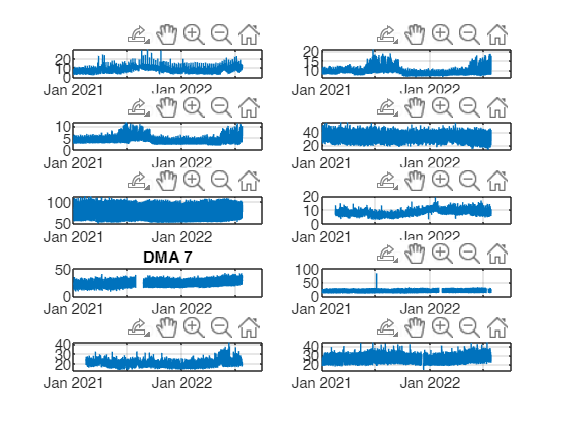

for i = 1:10
    subplot(5,2,i);
    plot(T,Q(:,i));  % Replace with your desired plot commands
    title(['DMA ' num2str(i)]);
    grid on
end

Remove low frequency trend

TotalQ = sum(Q'); % do not consider days with NAN
nonnan = ~isnan(TotalQ)

nonnan = 1×13680 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0



FourierTerms = 1;
w = 2 * pi/(365*24);
KDW = K(nonnan);
FDW = TotalQ(nonnan)';

A1 = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];
rcoef = A1\FDW

rcoef =   230.9970
   -8.2246
    0.5725


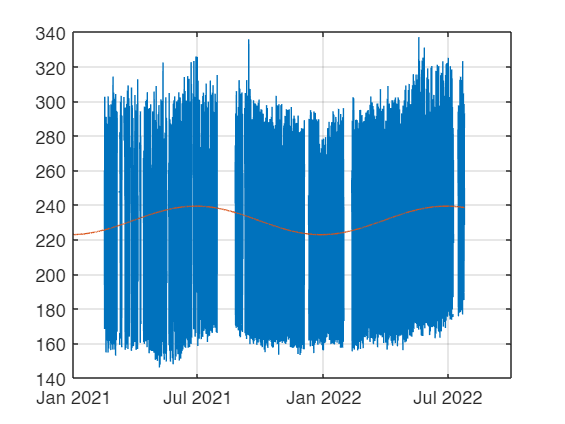


A0 = [ones(length(K),1) cos((1:FourierTerms)'*w*(K'))' sin((1:FourierTerms)'*w*(K'))'];
f4 = A0*rcoef;

figure
plot(T,TotalQ)
hold on
plot(T,f4)
grid on


figure
plot(T,TotalQ./f4)

Unrecognized function or variable 'SQ'.

MeanValue = nanmean(TotalQ./f4)
grid on

Compute MNF

nightStart = 0; % 00:00 in 24-hour format
nightEnd = 6; % 04:00 in 24-hour format
nightIndices = (T.Hour >= 0) & (T.Hour <= 6);

maxDate = max(T);
minDate = min(T);
% Calculate the difference in days
dateDifference = maxDate - minDate;
% Convert the duration to a scalar number of days
totalDays = floor(days(dateDifference))

totalDays = 569


for i=1:10
    DQ = reshape(Q((1:24*totalDays),i), 24, totalDays);
    mnf(i,:) = nanmin(DQ(1:6,:))
end

mnf =        NaN    2.3800    3.5700    2.9225    4.2200    2.7575    3.9450    3.1550    2.7375    3.7425    2.3100    3.7775    4.1800    3.8800    3.0575    3.1175       NaN       NaN    3.2000    3.3975    2.7050    3.9500    2.7625    3.7425    3.6525    3.2575    4.4700    3.1800    3.6300    3.7325    2.8525    4.0500    2.5375    4.3725    3.4825    4.1150    3.5900    3.2575    3.4825    3.7975    3.7825    2.2925    4.9250    3.8875    3.8475    5.0425    3.1300    3.2575    3.6775    3.1600


mnf =        NaN    2.3800    3.5700    2.9225    4.2200    2.7575    3.9450    3.1550    2.7375    3.7425    2.3100    3.7775    4.1800    3.8800    3.0575    3.1175       NaN       NaN    3.2000    3.3975    2.7050    3.9500    2.7625    3.7425    3.6525    3.2575    4.4700    3.1800    3.6300    3.7325    2.8525    4.0500    2.5375    4.3725    3.4825    4.1150    3.5900    3.2575    3.4825    3.7975    3.7825    2.2925    4.9250    3.8875    3.8475    5.0425    3.1300    3.2575    3.6775    3.1600
       NaN    7.6550    7.5950    7.6600    7.7325    7.7375    7.6575    7.6075    7.6450    7.6950    7.7625    7.7750    9.7475    7.7500    7.8125    7.8225       NaN       NaN    7.9925    8.0250    7.9825    7.8875    7.8500    8.0725    7.9975    7.8100    9.3275    9.3000    7.6850    7.6675    7.6025    7.6800    7.6325    7.6775    7.7100    7.6450    7.6425    7.6300    7.6700    7.6800    7.6075    7.6450    7.9200    7.6500    7.6850    7.6000    7.6250    7.5900    7.8150   

mnf =        NaN    2.3800    3.5700    2.9225    4.2200    2.7575    3.9450    3.1550    2.7375    3.7425    2.3100    3.7775    4.1800    3.8800    3.0575    3.1175       NaN       NaN    3.2000    3.3975    2.7050    3.9500    2.7625    3.7425    3.6525    3.2575    4.4700    3.1800    3.6300    3.7325    2.8525    4.0500    2.5375    4.3725    3.4825    4.1150    3.5900    3.2575    3.4825    3.7975    3.7825    2.2925    4.9250    3.8875    3.8475    5.0425    3.1300    3.2575    3.6775    3.1600
       NaN    7.6550    7.5950    7.6600    7.7325    7.7375    7.6575    7.6075    7.6450    7.6950    7.7625    7.7750    9.7475    7.7500    7.8125    7.8225       NaN       NaN    7.9925    8.0250    7.9825    7.8875    7.8500    8.0725    7.9975    7.8100    9.3275    9.3000    7.6850    7.6675    7.6025    7.6800    7.6325    7.6775    7.7100    7.6450    7.6425    7.6300    7.6700    7.6800    7.6075    7.6450    7.9200    7.6500    7.6850    7.6000    7.6250    7.5900    7.8150   

mnf =        NaN    2.3800    3.5700    2.9225    4.2200    2.7575    3.9450    3.1550    2.7375    3.7425    2.3100    3.7775    4.1800    3.8800    3.0575    3.1175       NaN       NaN    3.2000    3.3975    2.7050    3.9500    2.7625    3.7425    3.6525    3.2575    4.4700    3.1800    3.6300    3.7325    2.8525    4.0500    2.5375    4.3725    3.4825    4.1150    3.5900    3.2575    3.4825    3.7975    3.7825    2.2925    4.9250    3.8875    3.8475    5.0425    3.1300    3.2575    3.6775    3.1600
       NaN    7.6550    7.5950    7.6600    7.7325    7.7375    7.6575    7.6075    7.6450    7.6950    7.7625    7.7750    9.7475    7.7500    7.8125    7.8225       NaN       NaN    7.9925    8.0250    7.9825    7.8875    7.8500    8.0725    7.9975    7.8100    9.3275    9.3000    7.6850    7.6675    7.6025    7.6800    7.6325    7.6775    7.7100    7.6450    7.6425    7.6300    7.6700    7.6800    7.6075    7.6450    7.9200    7.6500    7.6850    7.6000    7.6250    7.5900    7.8150   

mnf =        NaN    2.3800    3.5700    2.9225    4.2200    2.7575    3.9450    3.1550    2.7375    3.7425    2.3100    3.7775    4.1800    3.8800    3.0575    3.1175       NaN       NaN    3.2000    3.3975    2.7050    3.9500    2.7625    3.7425    3.6525    3.2575    4.4700    3.1800    3.6300    3.7325    2.8525    4.0500    2.5375    4.3725    3.4825    4.1150    3.5900    3.2575    3.4825    3.7975    3.7825    2.2925    4.9250    3.8875    3.8475    5.0425    3.1300    3.2575    3.6775    3.1600
       NaN    7.6550    7.5950    7.6600    7.7325    7.7375    7.6575    7.6075    7.6450    7.6950    7.7625    7.7750    9.7475    7.7500    7.8125    7.8225       NaN       NaN    7.9925    8.0250    7.9825    7.8875    7.8500    8.0725    7.9975    7.8100    9.3275    9.3000    7.6850    7.6675    7.6025    7.6800    7.6325    7.6775    7.7100    7.6450    7.6425    7.6300    7.6700    7.6800    7.6075    7.6450    7.9200    7.6500    7.6850    7.6000    7.6250    7.5900    7.8150   

mnf =        NaN    2.3800    3.5700    2.9225    4.2200    2.7575    3.9450    3.1550    2.7375    3.7425    2.3100    3.7775    4.1800    3.8800    3.0575    3.1175       NaN       NaN    3.2000    3.3975    2.7050    3.9500    2.7625    3.7425    3.6525    3.2575    4.4700    3.1800    3.6300    3.7325    2.8525    4.0500    2.5375    4.3725    3.4825    4.1150    3.5900    3.2575    3.4825    3.7975    3.7825    2.2925    4.9250    3.8875    3.8475    5.0425    3.1300    3.2575    3.6775    3.1600
       NaN    7.6550    7.5950    7.6600    7.7325    7.7375    7.6575    7.6075    7.6450    7.6950    7.7625    7.7750    9.7475    7.7500    7.8125    7.8225       NaN       NaN    7.9925    8.0250    7.9825    7.8875    7.8500    8.0725    7.9975    7.8100    9.3275    9.3000    7.6850    7.6675    7.6025    7.6800    7.6325    7.6775    7.7100    7.6450    7.6425    7.6300    7.6700    7.6800    7.6075    7.6450    7.9200    7.6500    7.6850    7.6000    7.6250    7.5900    7.8150   

mnf =        NaN    2.3800    3.5700    2.9225    4.2200    2.7575    3.9450    3.1550    2.7375    3.7425    2.3100    3.7775    4.1800    3.8800    3.0575    3.1175       NaN       NaN    3.2000    3.3975    2.7050    3.9500    2.7625    3.7425    3.6525    3.2575    4.4700    3.1800    3.6300    3.7325    2.8525    4.0500    2.5375    4.3725    3.4825    4.1150    3.5900    3.2575    3.4825    3.7975    3.7825    2.2925    4.9250    3.8875    3.8475    5.0425    3.1300    3.2575    3.6775    3.1600
       NaN    7.6550    7.5950    7.6600    7.7325    7.7375    7.6575    7.6075    7.6450    7.6950    7.7625    7.7750    9.7475    7.7500    7.8125    7.8225       NaN       NaN    7.9925    8.0250    7.9825    7.8875    7.8500    8.0725    7.9975    7.8100    9.3275    9.3000    7.6850    7.6675    7.6025    7.6800    7.6325    7.6775    7.7100    7.6450    7.6425    7.6300    7.6700    7.6800    7.6075    7.6450    7.9200    7.6500    7.6850    7.6000    7.6250    7.5900    7.8150   

mnf =        NaN    2.3800    3.5700    2.9225    4.2200    2.7575    3.9450    3.1550    2.7375    3.7425    2.3100    3.7775    4.1800    3.8800    3.0575    3.1175       NaN       NaN    3.2000    3.3975    2.7050    3.9500    2.7625    3.7425    3.6525    3.2575    4.4700    3.1800    3.6300    3.7325    2.8525    4.0500    2.5375    4.3725    3.4825    4.1150    3.5900    3.2575    3.4825    3.7975    3.7825    2.2925    4.9250    3.8875    3.8475    5.0425    3.1300    3.2575    3.6775    3.1600
       NaN    7.6550    7.5950    7.6600    7.7325    7.7375    7.6575    7.6075    7.6450    7.6950    7.7625    7.7750    9.7475    7.7500    7.8125    7.8225       NaN       NaN    7.9925    8.0250    7.9825    7.8875    7.8500    8.0725    7.9975    7.8100    9.3275    9.3000    7.6850    7.6675    7.6025    7.6800    7.6325    7.6775    7.7100    7.6450    7.6425    7.6300    7.6700    7.6800    7.6075    7.6450    7.9200    7.6500    7.6850    7.6000    7.6250    7.5900    7.8150   

mnf =        NaN    2.3800    3.5700    2.9225    4.2200    2.7575    3.9450    3.1550    2.7375    3.7425    2.3100    3.7775    4.1800    3.8800    3.0575    3.1175       NaN       NaN    3.2000    3.3975    2.7050    3.9500    2.7625    3.7425    3.6525    3.2575    4.4700    3.1800    3.6300    3.7325    2.8525    4.0500    2.5375    4.3725    3.4825    4.1150    3.5900    3.2575    3.4825    3.7975    3.7825    2.2925    4.9250    3.8875    3.8475    5.0425    3.1300    3.2575    3.6775    3.1600
       NaN    7.6550    7.5950    7.6600    7.7325    7.7375    7.6575    7.6075    7.6450    7.6950    7.7625    7.7750    9.7475    7.7500    7.8125    7.8225       NaN       NaN    7.9925    8.0250    7.9825    7.8875    7.8500    8.0725    7.9975    7.8100    9.3275    9.3000    7.6850    7.6675    7.6025    7.6800    7.6325    7.6775    7.7100    7.6450    7.6425    7.6300    7.6700    7.6800    7.6075    7.6450    7.9200    7.6500    7.6850    7.6000    7.6250    7.5900    7.8150   

mnf =        NaN    2.3800    3.5700    2.9225    4.2200    2.7575    3.9450    3.1550    2.7375    3.7425    2.3100    3.7775    4.1800    3.8800    3.0575    3.1175       NaN       NaN    3.2000    3.3975    2.7050    3.9500    2.7625    3.7425    3.6525    3.2575    4.4700    3.1800    3.6300    3.7325    2.8525    4.0500    2.5375    4.3725    3.4825    4.1150    3.5900    3.2575    3.4825    3.7975    3.7825    2.2925    4.9250    3.8875    3.8475    5.0425    3.1300    3.2575    3.6775    3.1600
       NaN    7.6550    7.5950    7.6600    7.7325    7.7375    7.6575    7.6075    7.6450    7.6950    7.7625    7.7750    9.7475    7.7500    7.8125    7.8225       NaN       NaN    7.9925    8.0250    7.9825    7.8875    7.8500    8.0725    7.9975    7.8100    9.3275    9.3000    7.6850    7.6675    7.6025    7.6800    7.6325    7.6775    7.7100    7.6450    7.6425    7.6300    7.6700    7.6800    7.6075    7.6450    7.9200    7.6500    7.6850    7.6000    7.6250    7.5900    7.8150   